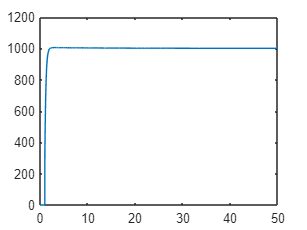

%   PID Calibration Script
%   Author: Vignesh Babu A.


%Runtime Calibration of Kp, Ki, Kd
Kp= 5786.7;
Ki=466;
Kd=295;
simulationOutput = sim('A_CruiseControl_Task3');


%Extraction of Simulation data
simulationOutputSignals = simulationOutput.yout;
input = simulationOutputSignals{1};
output= simulationOutputSignals{2};

outputTimeData= simulationOutputSignals{2}.Values.time;
outputSignalData= simulationOutputSignals{2}.Values.Data;

%Plotting Output Signal
plot(outputTimeData,outputSignalData);

FinalValue=output.Values.Data(end);


%-------Overshoot check---------
for i = output.Values.Data'
    if(i >input.Values.Data(end)+(input.Values.Data(end)*0.05))
        OverShootStatus = true;
        break
    else
        OverShootStatus=false;
        continue
    end
end
fprintf("Overshoot = %d\n",OverShootStatus);

Overshoot = 0




%------SteadyStateErrorCheck--------
currentFinalOutputValue = output.Values.Data(end)

currentFinalOutputValue =      1.000103489703574e+03


input.Values.Data(end)

ans =         1000


if(currentFinalOutputValue == single(input.Values.Data(end)))
    SteadyState=0
else
    SteadyState=1
end

SteadyState =      1



%-----------Report-------------
fprintf("Test Result:\n" + ...
    "Kp = %f\n" + ...
    "ki = %f\n" + ...
    "Kd= %f\n",Kp, Ki, Kd);

Test Result:
Kp = 5786.700000
ki = 466.000000
Kd= 295.000000
